clear all ,clc;
% Loading a Data file 
data = load("C:/Users/aniru/Desktop/BME 526/Assignment 1/data/09.mat");

% Access the 'wave' and 'time' vector
time = data.time;
wave = data.wave;

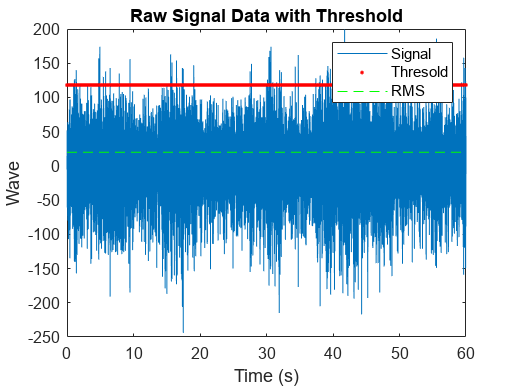

% a. To Calculate the magnitude of the signal
signal_magnitude = rms(wave);

% C. To Calculate the Variance of signal
signal_var = var(wave);

% d. Rational for signal variance: Variance is a measure of the spread
% of data points, indicating how much the signal values deviate from their mean.

% e. To Calculate the signal-to-noise ratio (SNR)
snr = signal_magnitude/sqrt(signal_var);

% f. Determine the threshold for detecting action potentials
threshold_multiple = 0.3;
threshold = threshold_multiple * signal_var;

% g. To plot the raw (time x wave) data and a line indicating the threshold used.
figure;
plot(time, wave);
hold on;
% Plot threshold line
threshold_line = ones(size(time)) * threshold;
plot(time, threshold_line, 'r.');
plot(time, signal_magnitude*ones(size(time)), 'g--');
xlabel('Time (s)');
ylabel('Wave');
legend("Signal","Thresold","RMS")
title('Raw Signal Data with Threshold');


% h. To build a matrix of putative action potential data and a matrix of noise data.
[peaks,peak_locs] = findpeaks(wave,"MinPeakHeight",threshold,"MinPeakDistance",0.001*30000);
action_potentials = zeros(3000, length(peak_locs)); % Assuming 1-2 ms duration and 30kHz sampling rate
noise_data = zeros(3000,length(action_potentials));
for i = 1:length(peak_locs)
    action_potentials(:, i) = wave(peak_locs(i)-1499:peak_locs(i)+1500);
end
for i = 1:length(action_potentials)
    noise_data(:, i) = wave(randi(length(wave), 1, 3000));
end

% h. Other method for generating noise matrix (replace with your method)
% noise_data = randn(300, length(action_potentials));

% h. Describe results
% Action potential matrix (action_potentials) contains snippets around threshold crossings.
% Noise matrix (noise_data) is generated either by random selection or another method.

% 3. Principal component analysis(PCA) 

% create a centroid 
centered_data = action_potentials - mean(action_potentials,1);

% calculate the covariance matrix 
cov_matrix = cov(centered_data);

%calculate the eigen value and vector 
%[eigen_vectors,eigen_val ]= eig(cov_matrix);
[U, S, V] = svd(centered_data);

% Project the data onto the principal components
projected_data = centered_data * V;

% Calculate the total variance in the data
total_variance = sum(diag(S));

% Calculate the cumulative explained variance
cumulative_explained_variance = cumsum(diag(S)) / total_variance;

% Determine the number of components that explain a certain percentage of variance
explained_variance_threshold = 0.95; % Adjust as needed
num_components = find(cumulative_explained_variance >= explained_variance_threshold, 1);

% Select the first 'num_components' principal components as the signal
signal_components = V(:, 1:num_components);

% Select the remaining components as noise
noise_components = V(:, num_components+1:end);

% Visualize the explained variance
% figure;
% plot(1:num_components, cumulative_explained_variance(1:num_components), 'bo-');
% xlabel('Number of Components');
% ylabel('Cumulative Explained Variance');
% title('Explained Variance by Principal Components');

% Now, 'signal_components' contains the principal components of the signal,
% and 'noise_components' contains the principal components of the noise.

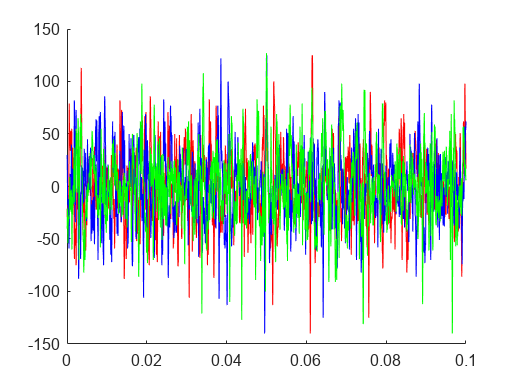

% 4) Plot PCA results
% a. Plot individual action potential snippets, mean waveform, and standard error
figure;
hold on;

% Colors for individual neurons
neuron_colors = {'r', 'b', 'g'};

% Plot individual action potential snippets
for i = 1:min(size(action_potentials, 2), numel(neuron_colors))
    snippet_time = (1:size(action_potentials, 1)) / 30000; % Assuming 30kHz sampling rate
    plot(snippet_time, action_potentials(:, i), neuron_colors{i});
end

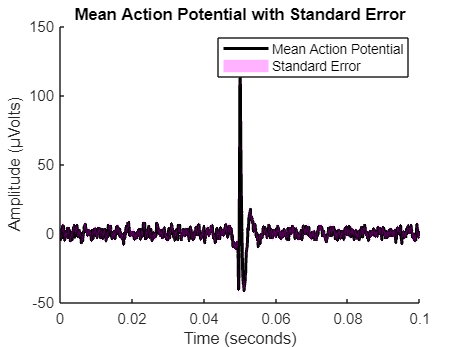


% Plot mean action potential waveform
mean_waveform = mean(action_potentials, 2);
mean_time = (1:length(mean_waveform)) / 30000; % Assuming 30kHz sampling rate
% plot(mean_time, mean_waveform, 'k', 'LineWidth', 2);

% Plot standard error of the mean waveform
std_error = std(action_potentials, 0, 2) / sqrt(size(action_potentials, 2));
%shadedErrorBar(time, mean_waveform, std_error, 'lineprops', 'm');
% Plot standard error of the mean waveform using MATLAB built-in functions
upper_bound = mean_waveform + std_error;
lower_bound = mean_waveform - std_error;

figure;
hold on;
plot(mean_time, mean_waveform, 'k', 'LineWidth', 2);
fill([mean_time, fliplr(mean_time)], [upper_bound', fliplr(lower_bound')], 'm', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
xlabel('Time (seconds)');
ylabel('Amplitude (μVolts)');
title('Mean Action Potential with Standard Error');
legend('Mean Action Potential', 'Standard Error');
hold off;

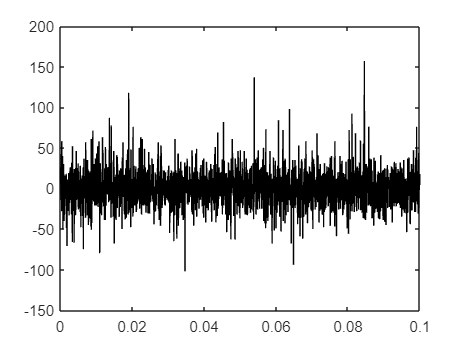



% Plot individual noise snippets
for i = 1:size(noise_data, 2)
    snippet_time = (1:size(noise_data, 1)) / 30000; % Assuming 30kHz sampling rate
    plot(snippet_time, noise_data(:, i), 'k');
end

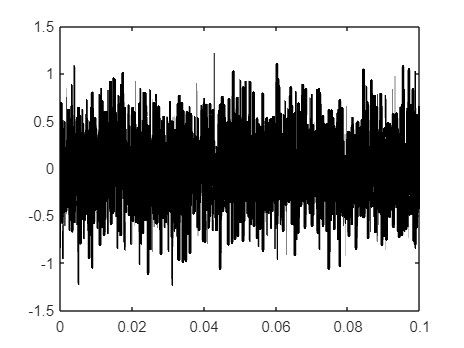


% Plot mean noise waveform
mean_noise_waveform = mean(noise_data, 2);
mean_noise_time = (1:length(mean_noise_waveform)) / 30000; % Assuming 30kHz sampling rate
plot(mean_noise_time, mean_noise_waveform, 'k', 'LineWidth', 2);

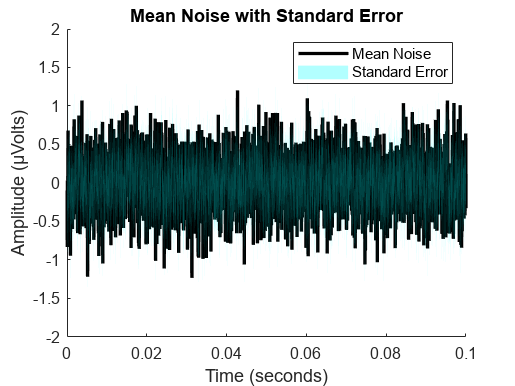


% Calculate standard error of the mean waveform for noise
std_error_noise = std(noise_data, 0, 2) / sqrt(size(noise_data, 2));

% Plot standard error of all noise snippets using MATLAB built-in functions
upper_bound_noise = mean_noise_waveform + std_error_noise;
lower_bound_noise = mean_noise_waveform - std_error_noise;

figure;
hold on;
plot(mean_noise_time, mean_noise_waveform, 'k', 'LineWidth', 2);
fill([mean_noise_time, fliplr(mean_noise_time)], [upper_bound_noise', fliplr(lower_bound_noise')], 'c', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
xlabel('Time (seconds)');
ylabel('Amplitude (μVolts)');
title('Mean Noise with Standard Error');
legend('Mean Noise', 'Standard Error');
hold off;


% c. Briefly discuss the results
% Comments: The first figure provides a visual representation of individual action potential snippets, mean waveform, and standard error. Different colors represent different neurons. The second figure shows a 3D scatter plot of the first three principal components, where action potentials and noise are differentiated. This visualization can help in understanding the separation of clusters based on PCA components.

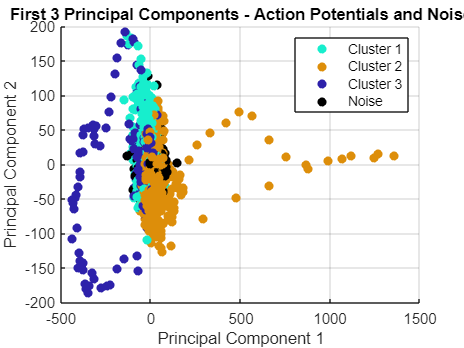

% Cluster the combined data (action potential and noise) using k-means clustering
combined_data = [action_potentials,noise_data];
num_clusters = 3; % Specify the number of clusters
idx = kmeans(combined_data, num_clusters);

% Plot the first three principal components of clustered action potential and noise data
figure;
hold on;

% Plot action potentials with different colors for each cluster
for cluster = 1:num_clusters
    scatter3(projected_data(idx == cluster, 1), ...
             projected_data(idx == cluster, 2), ...
             projected_data(idx == cluster, 3), ...
             'filled', 'MarkerFaceColor', rand(1,3));
end
hold on;
% Plot noise data in black
scatter3(noise_data(:, 1), noise_data(:, 2), noise_data(:, 3), 'filled', 'MarkerFaceColor', 'k');
hold on;
xlabel('Principal Component 1');
ylabel('Principal Component 2');
zlabel('Principal Component 3');
title('First 3 Principal Components - Action Potentials and Noise');
legend('Cluster 1', 'Cluster 2', 'Cluster 3', 'Noise');
grid on;

clear all ,clc;
% Loading a Data file 
data = load("C:/Users/aniru/Desktop/BME 526/Assignment 1/data/12.mat");

% Access the 'wave' and 'time' vector
time = data.time;
wave = data.wave;

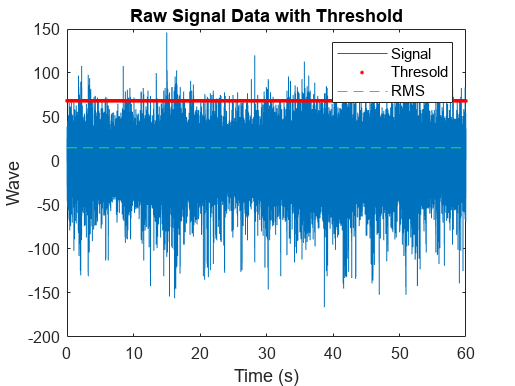

% a. To Calculate the magnitude of the signal
signal_magnitude = rms(wave);

% C. To Calculate the Variance of signal
signal_var = var(wave);

% d. Rational for signal variance: Variance is a measure of the spread
% of data points, indicating how much the signal values deviate from their mean.

% e. To Calculate the signal-to-noise ratio (SNR)
snr = signal_magnitude/sqrt(signal_var);

% f. Determine the threshold for detecting action potentials
threshold_multiple = 0.3;
threshold = threshold_multiple * signal_var;

% g. To plot the raw (time x wave) data and a line indicating the threshold used.
figure;
plot(time, wave);
hold on;
% Plot threshold line
threshold_line = ones(size(time)) * threshold;
plot(time, threshold_line, 'r.');
plot(time, signal_magnitude*ones(size(time)), 'g--');
xlabel('Time (s)');
ylabel('Wave');
legend("Signal","Thresold","RMS")
title('Raw Signal Data with Threshold');


% h. To build a matrix of putative action potential data and a matrix of noise data.
[peaks,peak_locs] = findpeaks(wave,"MinPeakHeight",threshold,"MinPeakDistance",0.001*30000);
action_potentials = zeros(3000, length(peak_locs)); % Assuming 1-2 ms duration and 30kHz sampling rate
noise_data = zeros(3000,length(action_potentials));
for i = 1:length(peak_locs)
    action_potentials(:, i) = wave(peak_locs(i)-1499:peak_locs(i)+1500);
end
for i = 1:length(action_potentials)
    noise_data(:, i) = wave(randi(length(wave), 1, 3000));
end

% h. Other method for generating noise matrix (replace with your method)
% noise_data = randn(300, length(action_potentials));

% h. Describe results
% Action potential matrix (action_potentials) contains snippets around threshold crossings.
% Noise matrix (noise_data) is generated either by random selection or another method.

% 3. Principal component analysis(PCA) 

% create a centroid 
centered_data = action_potentials - mean(action_potentials,1);

% calculate the covariance matrix 
cov_matrix = cov(centered_data);

%calculate the eigen value and vector 
%[eigen_vectors,eigen_val ]= eig(cov_matrix);
[U, S, V] = svd(centered_data);

% Project the data onto the principal components
projected_data = centered_data * V;

% Calculate the total variance in the data
total_variance = sum(diag(S));

% Calculate the cumulative explained variance
cumulative_explained_variance = cumsum(diag(S)) / total_variance;

% Determine the number of components that explain a certain percentage of variance
explained_variance_threshold = 0.95; % Adjust as needed
num_components = find(cumulative_explained_variance >= explained_variance_threshold, 1);

% Select the first 'num_components' principal components as the signal
signal_components = V(:, 1:num_components);

% Select the remaining components as noise
noise_components = V(:, num_components+1:end);

% Visualize the explained variance
% figure;
% plot(1:num_components, cumulative_explained_variance(1:num_components), 'bo-');
% xlabel('Number of Components');
% ylabel('Cumulative Explained Variance');
% title('Explained Variance by Principal Components');

% Now, 'signal_components' contains the principal components of the signal,
% and 'noise_components' contains the principal components of the noise.
% You can use these components for further analysis or clustering.

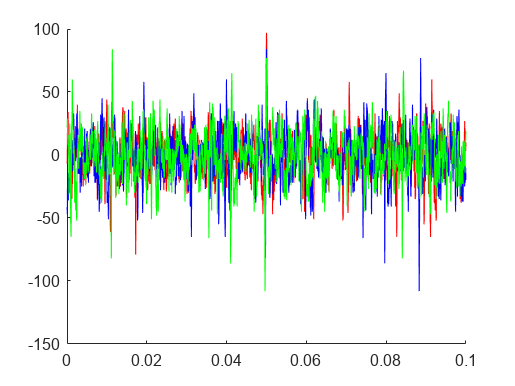

% 4) Plot PCA results
% a. Plot individual action potential snippets, mean waveform, and standard error
figure;
hold on;

% Colors for individual neurons
neuron_colors = {'r', 'b', 'g'};

% Plot individual action potential snippets
for i = 1:min(size(action_potentials, 2), numel(neuron_colors))
    snippet_time = (1:size(action_potentials, 1)) / 30000; % Assuming 30kHz sampling rate
    plot(snippet_time, action_potentials(:, i), neuron_colors{i});
end

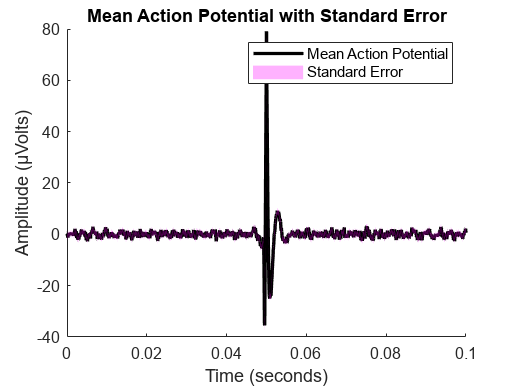


% Plot mean action potential waveform
mean_waveform = mean(action_potentials, 2);
mean_time = (1:length(mean_waveform)) / 30000; % Assuming 30kHz sampling rate
% plot(mean_time, mean_waveform, 'k', 'LineWidth', 2);

% Plot standard error of the mean waveform
std_error = std(action_potentials, 0, 2) / sqrt(size(action_potentials, 2));
%shadedErrorBar(time, mean_waveform, std_error, 'lineprops', 'm');
% Plot standard error of the mean waveform using MATLAB built-in functions
upper_bound = mean_waveform + std_error;
lower_bound = mean_waveform - std_error;

figure;
hold on;
plot(mean_time, mean_waveform, 'k', 'LineWidth', 2);
fill([mean_time, fliplr(mean_time)], [upper_bound', fliplr(lower_bound')], 'm', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
xlabel('Time (seconds)');
ylabel('Amplitude (μVolts)');
title('Mean Action Potential with Standard Error');
legend('Mean Action Potential', 'Standard Error');
hold off;



% Plot individual noise snippets
for i = 1:size(noise_data, 2)
    snippet_time = (1:size(noise_data, 1)) / 30000; % Assuming 30kHz sampling rate
    plot(snippet_time, noise_data(:, i), 'k');
end

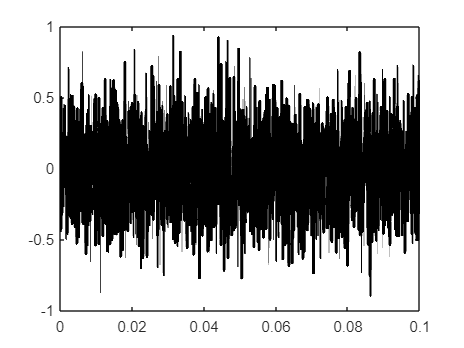


% Plot mean noise waveform
mean_noise_waveform = mean(noise_data, 2);
mean_noise_time = (1:length(mean_noise_waveform)) / 30000; % Assuming 30kHz sampling rate
plot(mean_noise_time, mean_noise_waveform, 'k', 'LineWidth', 2);

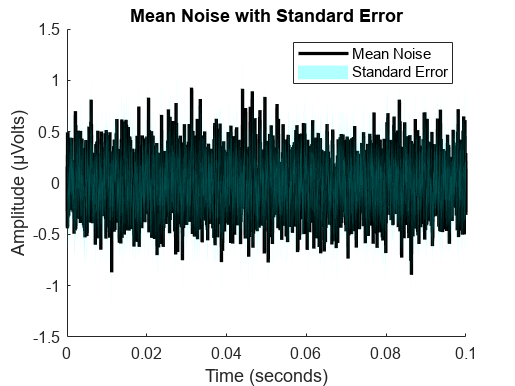


% Calculate standard error of the mean waveform for noise
std_error_noise = std(noise_data, 0, 2) / sqrt(size(noise_data, 2));

% Plot standard error of all noise snippets using MATLAB built-in functions
upper_bound_noise = mean_noise_waveform + std_error_noise;
lower_bound_noise = mean_noise_waveform - std_error_noise;

figure;
hold on;
plot(mean_noise_time, mean_noise_waveform, 'k', 'LineWidth', 2);
fill([mean_noise_time, fliplr(mean_noise_time)], [upper_bound_noise', fliplr(lower_bound_noise')], 'c', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
xlabel('Time (seconds)');
ylabel('Amplitude (μVolts)');
title('Mean Noise with Standard Error');
legend('Mean Noise', 'Standard Error');
hold off;

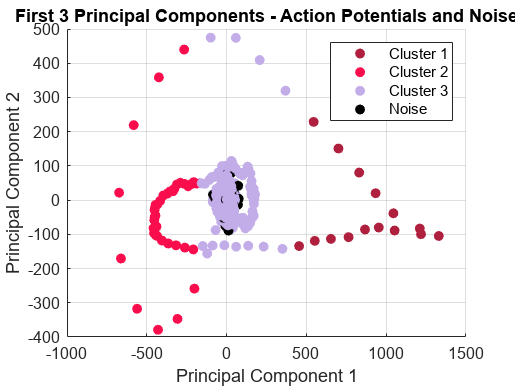

% Cluster the combined data (action potential and noise) using k-means clustering
combined_data = [action_potentials,noise_data];
num_clusters = 3; % Specify the number of clusters
idx = kmeans(combined_data, num_clusters);

% Plot the first three principal components of clustered action potential and noise data
figure;
hold on;

% Plot action potentials with different colors for each cluster
for cluster = 1:num_clusters
    scatter3(projected_data(idx == cluster, 1), ...
             projected_data(idx == cluster, 2), ...
             projected_data(idx == cluster, 3), ...
             'filled', 'MarkerFaceColor', rand(1,3));
end
hold on;
% Plot noise data in black
scatter3(noise_data(:, 1), noise_data(:, 2), noise_data(:, 3), 'filled', 'MarkerFaceColor', 'k');
hold on;
xlabel('Principal Component 1');
ylabel('Principal Component 2');
zlabel('Principal Component 3');
title('First 3 Principal Components - Action Potentials and Noise');
legend('Cluster 1', 'Cluster 2', 'Cluster 3', 'Noise');
grid on;

%% c. Briefly discuss the results. Comments: The first figure provides a visual representation of individual action potential snippets, mean waveform, and standard error. Different colors represent different neurons. The second figure shows a 3D scatter plot of the first three principal components, where action potentials and noise are differentiated. This visualization can help in understanding the separation of clusters based on PCA components.

## I utilized 9.mat and 12.mat files.

## I'm facing challenges in identifying the PCA clusters. I'm uncertain if my approach is correct. The noise appears to be integrated with the clusters of action potentials, making it difficult to distinguish them.